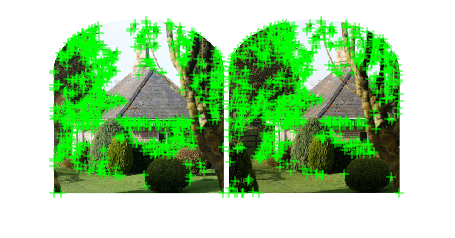

left = imread("left.png");
right = imread("right.png");
corners_left = detectHarrisFeatures(im2gray(left));
corners_right = detectHarrisFeatures(im2gray(right));
figure;
imshow([left,right]);
hold on;
quantity = 800;
strongest_left = corners_left.selectStrongest(quantity);
strongest_right = corners_right.selectStrongest(quantity);
plot(strongest_left.Location(:,1),strongest_left.Location(:,2),"g+");
plot(strongest_right.Location(:,1)+size(left,2),strongest_right.Location(:,2),"g+");

radius = 5;
offset_left = zeros(size(left)+[2*radius,2*radius,0]);
offset_left(radius+1:end-radius,radius+1:end-radius,:) = imgaussfilt(left,3);
offset_right = zeros(size(right)+[2*radius,2*radius,0]);
offset_right(radius+1:end-radius,radius+1:end-radius,:) = imgaussfilt(right,3);

minxy = uint32(strongest_right.Location);
maxxy = uint32(strongest_right.Location+2*radius);
descriptors_right = zeros(2*radius+1,2*radius+1,3,length(minxy));
for i=1:size(descriptors_right,4)
    descriptors_right(:,:,:,i) = offset_right(minxy(i,1):maxxy(i,1),minxy(i,2):maxxy(i,2),:);
end

selected_points = zeros(800,2);
selected_points(:,1) = randperm(quantity,size(selected_points,1))';
matched_points = zeros(size(selected_points));
matched_points(:,2) = 10^12;
remaining_selected = true(size(selected_points,1),1);
remaining_matched = true(size(matched_points,1),1);

for j=1:20
    for i=1:length(selected_points)
        if ~remaining_selected(i)
            continue
        end
        minxy = uint32(strongest_left.Location(selected_points(i,1),:));
        maxxy = uint32(strongest_left.Location(selected_points(i,1),:)+2*radius);
        descriptor_left = offset_left(minxy(1):maxxy(1),minxy(2):maxxy(2),:);
        sd = (descriptors_right(:,:,:,remaining_matched)-descriptor_left).^2;
        ssd = sum(sd,1:3);
        ssd = squeeze(ssd);
        [v,idx] = min(ssd);
        idx = find(remaining_matched==1,idx,"first");
        idx = idx(end);
        if v<matched_points(idx,2)
            if matched_points(idx,1)>0
                selected_points(matched_points(idx,1),2) = 0;
            end
            selected_points(i,2) = idx;
            matched_points(idx,1) = i;
            matched_points(idx,2) = v;
        end
    end
    remaining_selected = selected_points(:,2)==0;
    remaining_matched = matched_points(:,1)==0;
    sum(remaining_selected)
    if sum(remaining_selected)==0
        break
    end
end

ans = 451

ans = 305

ans = 249

ans = 216

ans = 198

ans = 190

ans = 177

ans = 172

ans = 165

ans = 161

ans = 157

ans = 154

ans = 148

ans = 142

ans = 137

ans = 133

ans = 129

ans = 123

ans = 115

ans = 110

old_selected_points = selected_points;
selected_points = selected_points(selected_points(:,2)~=0,:);

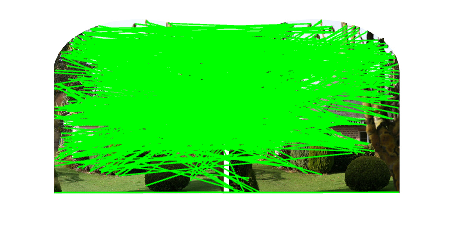

x1 = strongest_left.Location(selected_points(:,1),1);
y1 = strongest_left.Location(selected_points(:,1),2);
x2 = strongest_right.Location(selected_points(:,2),1)+size(left,2);
y2 = strongest_right.Location(selected_points(:,2),2);
figure;
imshow([left,right]);
hold on;
plot([x1,x2]',[y1,y2]',"g-");

slope_dev = 0.25;
length_dev = 1;
slopes = (y2-y1)./(x2-x1);
lengths = sqrt((y2-y1).^2.+(x2-x1).^2);
figure;
histogram(slopes)
m=mean(slopes)

m = single
-0.0272

s=slope_dev*std(slopes)

s = single
0.0926

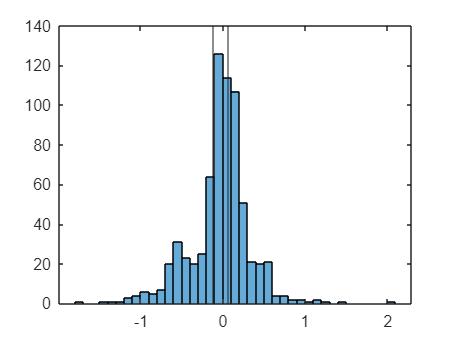

xline(m+s)
xline(m-s)

slope_inliers = (m-s)<slopes & slopes<(m+s);
figure;
histogram(lengths)
m=mean(lengths)

m = single
421.1759

s=length_dev*std(lengths)

s = single
88.9690

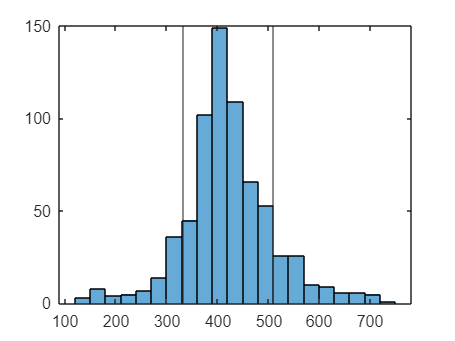

xline(m+s)
xline(m-s)

length_inliers = (m-s)<lengths & lengths<(m+s);
inliers = slope_inliers & length_inliers;
sum(inliers)

ans = 182

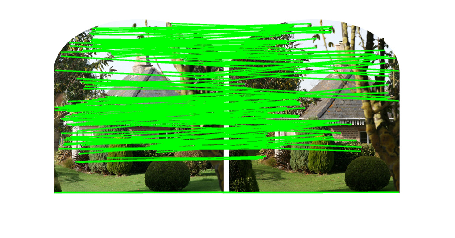

x1_filtered = strongest_left.Location(selected_points(inliers,1),1);
y1_filtered = strongest_left.Location(selected_points(inliers,1),2);
x2_filtered = strongest_right.Location(selected_points(inliers,2),1)+size(left,2);
y2_filtered = strongest_right.Location(selected_points(inliers,2),2);
figure;
imshow([left,right]);
hold on;
plot([x1_filtered,x2_filtered]',[y1_filtered,y2_filtered]',"g-");